# Some examples for the application of remezex()

## Example 1: exp()

*** Start of iteration 1 ***
Polynomial coefficients: 
0.500244, 1, 1
Error: 4.8309e-12
Error function root #1 in interval [0, 0.00026084]: 6.5097e-05
Error function root #2 in interval [0.00026084, 0.00074868]: 0.00048834
Error function root #3 in interval [0.00074868, 0.00097656]: 0.00091146
Extremum #1 in interval [0, 6.5097e-05] at 0 with error 4.831e-12
Extremum #2 in interval [6.5097e-05, 0.00048834] at 0.00024398 with error 4.865e-12
Extremum #3 in interval [0.00048834, 0.00091146] at 0.00073263 with error 4.863e-12
Extremum #4 in interval [0.00091146, 0.00097656] at 0.00097656 with error 4.831e-12
Node with largest error e(0.00026084) = 4.865e-12
Shifting all points by:
0, -1.68542e-05, -1.60463e-05, 0


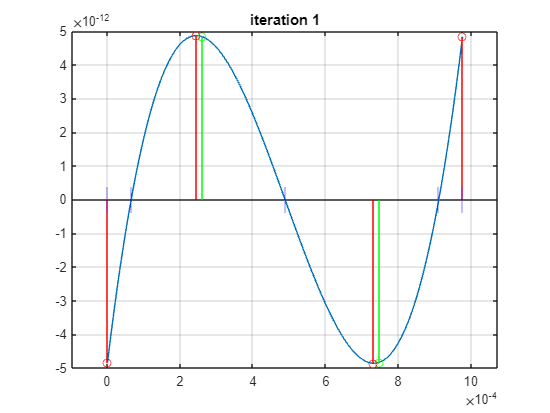

*** Start of iteration 2 ***
Polynomial coefficients: 
0.500244, 1, 1
Error: 4.853e-12
Error function root #1 in interval [0, 0.00024398]: 6.5421e-05
Error function root #2 in interval [0.00024398, 0.00073263]: 0.0004883
Error function root #3 in interval [0.00073263, 0.00097656]: 0.00091115
Extremum #1 in interval [0, 6.5421e-05] at 0 with error 4.853e-12
Extremum #2 in interval [6.5421e-05, 0.0004883] at 0.00024416 with error 4.853e-12
Extremum #3 in interval [0.0004883, 0.00091115] at 0.00073244 with error 4.853e-12
Extremum #4 in interval [0.00091115, 0.00097656] at 0.00097656 with error 4.853e-12
Node with largest error e(0) = 4.853e-12
Largest position shift 0 below threshold 9.3132e-10 --> exiting
Best approximation polynomial of order 2 over [0, 0.00097656] with max abs error 4.853e-12:
+5.002442124317668e-01 * x^2
+9.999999105567877e-01 * x^1
+1.000000000004853e+00


fun_str  = "exp()";
fun      = @(x) exp(x);
fun_der  = @(x) exp(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true, 'verbosity', 3);

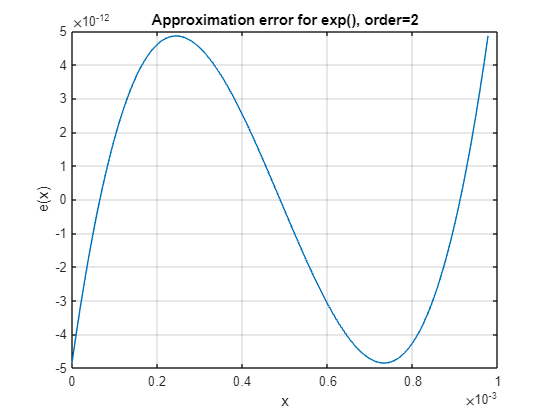

plot_demo(fun, fun_str, p, interval);

## Example 2: exp()

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'multi', true, 'verbosity', 2);

*** Start of iteration 1 ***
Polynomial coefficients: 
0.000313921, 0.0079092, 0.0776877, 0.377194, 0.934187, 0.994267
Error: 0.0057328
Error function root #1 in interval [-8, -7.4902]: -7.8477
Error function root #2 in interval [-7.4902, -5.9668]: -6.6795
Error function root #3 in interval [-5.9668, -3.9671]: -4.7453
Error function root #4 in interval [-3.9671, -1.9881]: -2.6357
Error function root #5 in interval [-1.9881, -0.49625]: -0.95377
Error function root #6 in interval [-0.49625, 0]: -0.10681
Extremum #1 in interval [-8, -7.8477] at -8 with error 0.0057328
Extremum #2 in interval [-7.8477, -6.6795] at -7.3915 with error 0.0059508
Extremum #3 in interval [-6.6795, -4.7453] at -5.7662 with error 0.0060486
Extremum #4 in interval [-4.7453, -2.6357] at -3.6613 with error 0.0063587
Extremum #5 in interval [-2.6357, -0.95377] at -1.7121 with error 0.0065242
Extremum #6 in interval [-0.95377, -0.10681] at -0.43097 with error 0.0058898
Extremum #7 in interval [-0.10681, 0] at 0 with e

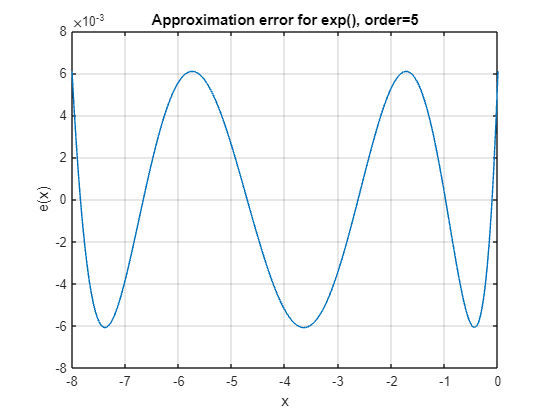

plot_demo(fun, fun_str, p, interval);

## Example 3: sin()

fun_str  = "sin()";
fun      = @(x) sin(x);
fun_der  = @(x) cos(x);
interval = [0, 2^(-10)];
order    = 2;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(2)=0.00023266 by 1.1449e-05
*** Start of iteration 2 ***
Shifting x(3)=0.00072354 by 8.8566e-06
*** Start of iteration 3 ***
Shifting x(2)=0.0002441 by 3.6333e-08
*** Start of iteration 4 ***
Shifting x(3)=0.0007324 by 2.6453e-08
*** Start of iteration 5 ***
Best approximation polynomial of order 2 over [0, 0.00097656] with max abs error 4.8506e-12:
-2.441406091975296e-04 * x^2
+1.000000089406958e+00 * x^1
-4.850637762513077e-12


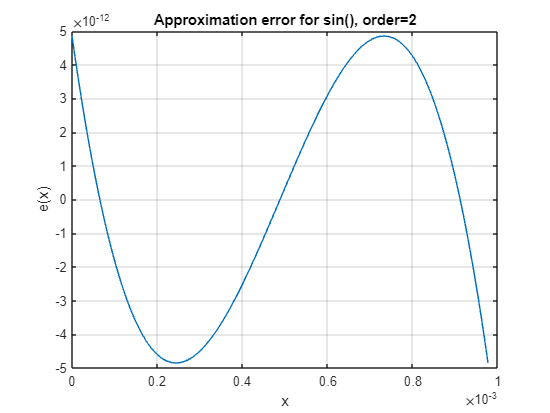

plot_demo(fun, fun_str, p, interval);

## Example 4: sin()

interval = [-8 0];
order    = 5;
[p, ~] = remezex(fun, fun_der, interval, order, 'verbosity', 1);

*** Start of iteration 1 ***
Shifting x(4)=-3.9418 by -0.34964
*** Start of iteration 2 ***
Shifting x(5)=-2.006 by -0.35043
*** Start of iteration 3 ***
Shifting x(6)=-0.52097 by -0.19051
*** Start of iteration 4 ***
Shifting x(3)=-5.8712 by -0.2444
*** Start of iteration 5 ***
Shifting x(2)=-7.5049 by 0.021175
*** Start of iteration 6 ***
Shifting x(5)=-2.3564 by 0.013023
*** Start of iteration 7 ***
Shifting x(4)=-4.2914 by 0.011836
*** Start of iteration 8 ***
Shifting x(6)=-0.71148 by 0.0030614
*** Start of iteration 9 ***
Shifting x(3)=-6.1156 by -0.0013358
*** Start of iteration 10 ***
Shifting x(2)=-7.4837 by -8.0257e-05
*** Start of iteration 11 ***
Shifting x(5)=-2.3434 by -2.3068e-05
*** Start of iteration 12 ***
Shifting x(4)=-4.2796 by 2.2288e-06
*** Start of iteration 13 ***
Shifting x(6)=-0.70842 by 9.2265e-07
*** Start of iteration 14 ***
Shifting x(2)=-7.4838 by -1.2604e-09
*** Start of iteration 15 ***
Best approximation polynomial of order 5 over [-8, 0] with max abs

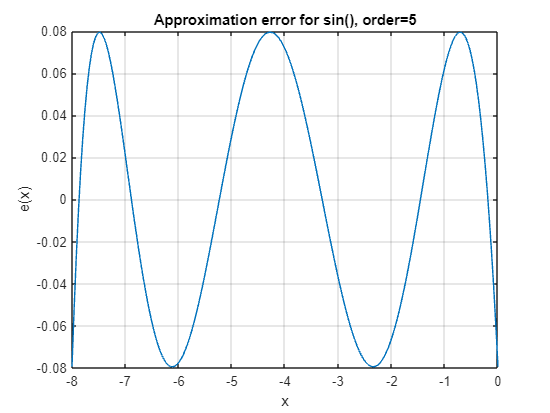

plot_demo(fun, fun_str, p, interval);

## Example 5: atan()

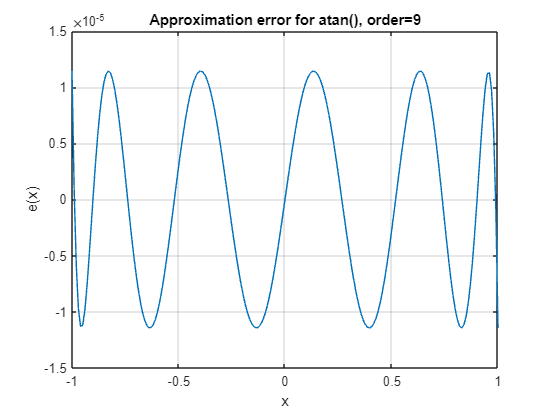

fun_str  = "atan()";
fun      = @(x) atan(x);
fun_der  = @(x) 1./(x.^2+1);
interval = [-1 1];
order    = 9;
[p, ~] = remezex(fun, fun_der, interval, order);
plot_demo(fun, fun_str, p, interval);

## Helper function

function plot_demo(fun, fun_str, p, interval)
    % plotting the error of the whole interval
    numTestPoints = 200;
    x = linspace(interval(1), interval(2), numTestPoints);
    e = fun(x) - polyval(p, x);
    figure();
    plot(x, e);
    xlabel('x'); ylabel('e(x)'); grid on;
    order = numel(p)-1;
    title("Approximation error for " + fun_str + ", order=" + order);
end